% img1 = I_copy;
img2 = mat2gray(I_copy);

mask = double(imbinarize(img1));
mask = imgaussfilt(mask,5).*5-1;

img2_clean= img2.*(1+mask*1);

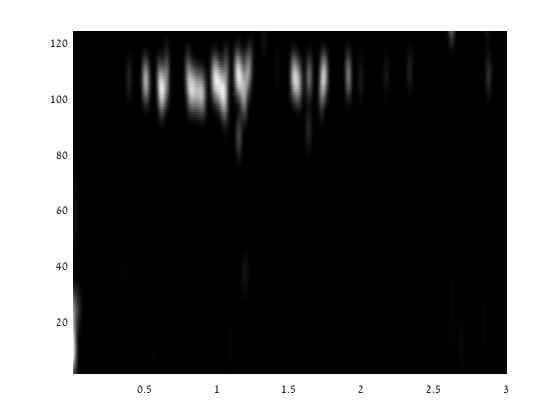

figure;
    hSurf= surface(mask,'EdgeColor','none');
 xTime = (1:numTimes)/new_fs;
    hSurf.XData = (xTime);
    
    axis tight
    colormap gray